## Course Example: Electricity Consumption

Load the electricity and price data.

load electricity
whos

  Name             Size            Bytes  Class     Attributes

  dollar2015       1x26              208  double              
  mth              1x12               96  double              
  price           12x26             2496  double              
  usage           12x26             2496  double              
  yr               1x26              208  double              



## Concatenating Arrays

Create and concatenate some matrices.

A = [1,2,3; 4,5,6; 7,8,9];
B = [A; 10 11 12]

B =      1     2     3
     4     5     6
     7     8     9
    10    11    12


%C = [A, 10;11;12] % error!
C = [A, [10;11;12]] % OK

C =      1     2     3    10
     4     5     6    11
     7     8     9    12


## Creating Matrices with Functions

Create some basic matrices.

A = ones(2,3)

A =      1     1     1
     1     1     1


B = zeros(2)

B =      0     0
     0     0


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = magic(3)

D =      8     1     6
     3     5     7
     4     9     2


Generate random numbers.

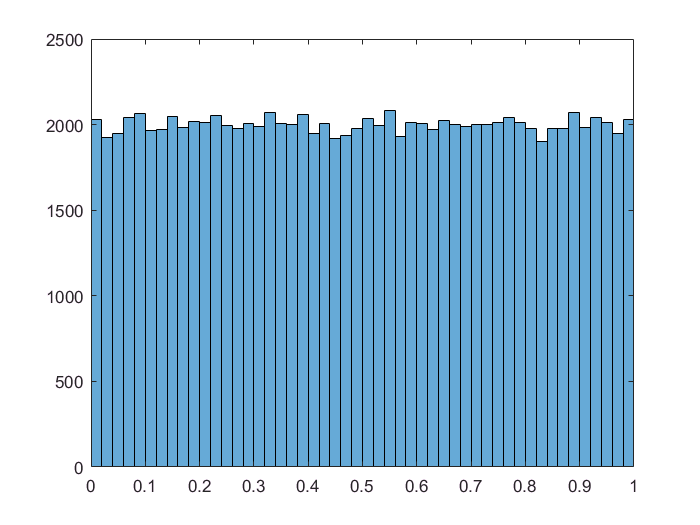

x1 = rand(1,1e5);
histogram(x1)

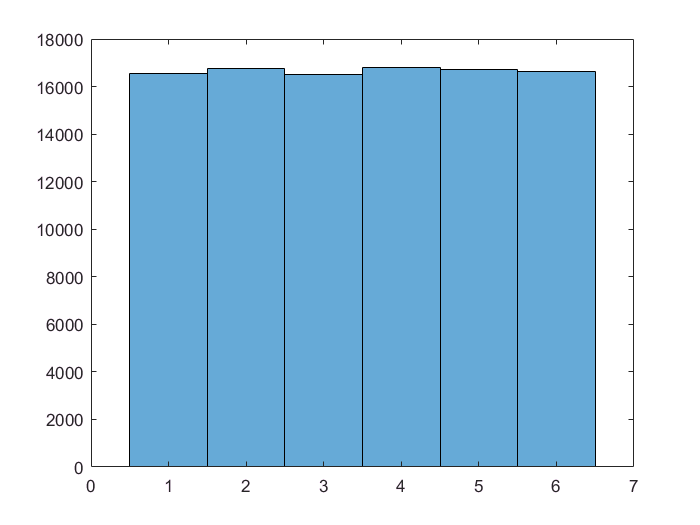

x2 = randi(6,1,1e5);
histogram(x2)

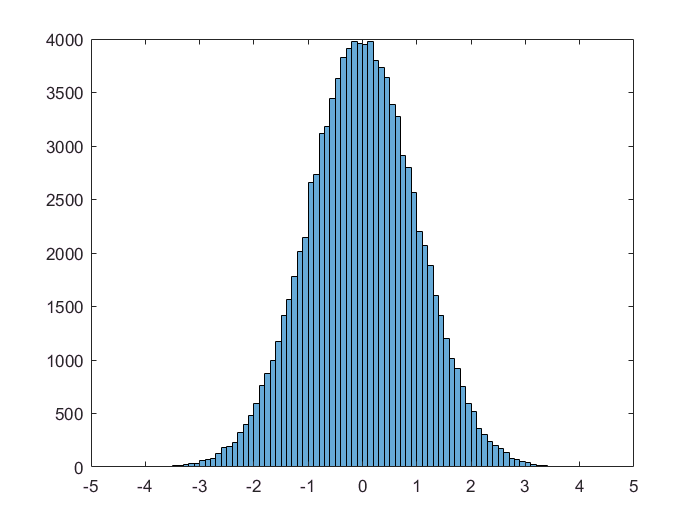

x3 = randn(1,1e5);
histogram(x3)

## Accessing Data in Matrices

Compare electricity usage in June and October (from 1990 to 2015).

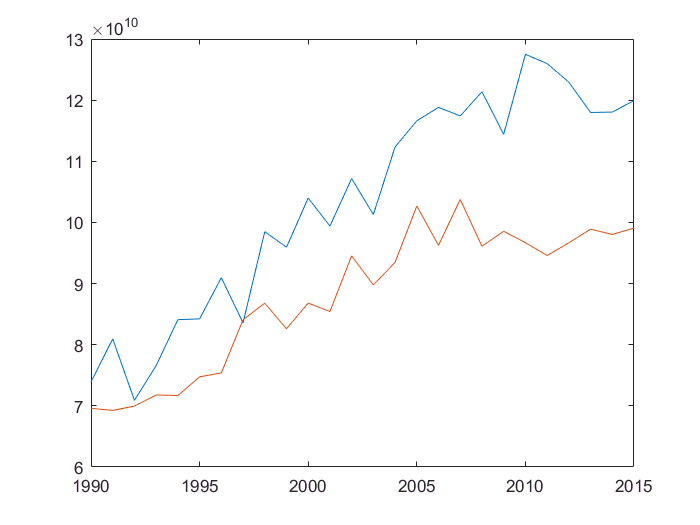

June = usage(6,:);
Oct = usage(10,:);
plot(yr,June)
hold on
plot(yr,Oct)
hold off

View the monthly electricity prices in 2015.

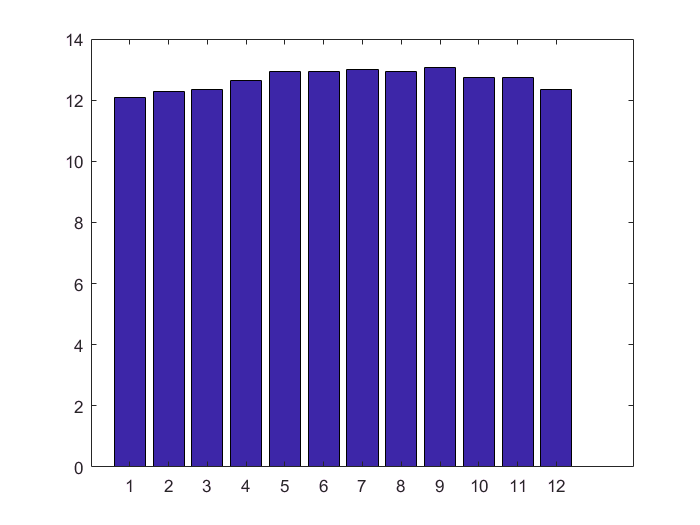

price2015 = price(:,end);
bar(mth,price2015)

## Matrix Operations

Convert prices from ¢/kWh to $/MWh.

price = price*1000/100;

Add simulated noise to the price data.

noise = randn(12,26);
nPrice = price + noise;

Attempt to calculate total revenue.

%revenue = price*usage

Check the dimensions of the variables.

whos price usage

  Name        Size            Bytes  Class     Attributes

  price      12x26             2496  double              
  usage      12x26             2496  double              



The dimensions are the same. Why didn’t this work?

## Array Operations

Calculate electricity revenues.

revenue = price.*usage

revenue =    1.0e+14 *

    0.6841    0.6952    0.7041    0.7254    0.8034    0.7581    0.8421    0.8351    0.8073    0.8427    0.8392    0.9827    0.9429    0.9946    1.0473    1.0672    1.1496    1.2599    1.3524    1.4954    1.5475    1.5771    1.4360    1.5100    1.7075    1.6638
    0.5572    0.6042    0.6389    0.6502    0.7037    0.6942    0.7502    0.7202    0.6902    0.6868    0.7600    0.8030    0.7907    0.8897    0.9363    0.9341    1.0243    1.2016    1.2045    1.2885    1.3374    1.3284    1.2424    1.3153    1.5338    1.5209
    0.5443    0.5751    0.5905    0.6478    0.6456    0.6468    0.7034    0.6709    0.6885    0.7066    0.6854    0.7721    0.7785    0.8312    0.8525    0.9235    1.0358    1.0854    1.1198    1.2014    1.2414    1.2090    1.1621    1.3016    1.3996    1.4427
    0.5015    0.5256    0.5497    0.5665    0.5766    0.5769    0.6148    0.6095    0.6103    0.6250    0.6219    0.6974    0.7151    0.7357    0.7628    0.8002    0.9220    0.9595    1.0075   

Calculate a ratio of prices.

priceInflation = price(:,end)./price(:,1)

priceInflation =     1.6873
    1.6429
    1.6308
    1.6429
    1.6269
    1.5967
    1.5881
    1.5698
    1.6013
    1.5827


Convert prices to 2015 equivalents using the value of $1 relative to 2015. Note the size of the result.

price2015 = price.*dollar2015

price2015 =    1.0e+03 *

    1.3006    1.2890    1.3002    1.2691    1.2374    1.2212    1.1715    1.1616    1.1446    1.0782    1.0539    1.0352    1.0629    1.0310    1.0339    1.0338    1.1224    1.1495    1.1163    1.2128    1.1404    1.1456    1.1776    1.1657    1.1668    1.2097
    1.3567    1.3235    1.3135    1.2789    1.2547    1.2457    1.1794    1.1782    1.1594    1.1275    1.0614    1.0762    1.0787    1.0331    1.0447    1.0629    1.1523    1.1309    1.1185    1.2355    1.1835    1.1654    1.1878    1.1830    1.1953    1.2287
    1.3732    1.3549    1.3526    1.2799    1.2923    1.2659    1.2212    1.2168    1.1646    1.1242    1.1149    1.1137    1.0762    1.0756    1.0812    1.0771    1.1603    1.1739    1.1504    1.2462    1.2071    1.2141    1.2073    1.1814    1.2267    1.2345
    1.3955    1.3882    1.3565    1.3336    1.3269    1.3082    1.2450    1.2373    1.1969    1.1509    1.1234    1.1321    1.1033    1.1359    1.1212    1.1195    1.2129    1.2149    1.2035 

Add a row vector and a column vector. Note the size of the result.

A = [1 2]

A =      1     2


B = [0;1;2;3]

B =      0
     1
     2
     3


C = A + B

C =      1     2
     2     3
     3     4
     4     5


## Matrix Mathematics

Use matrix-vector multiplication to calculate the weighted average of prices, weighted by the value of $1 relative to 2015.

w = dollar2015/sum(dollar2015)

w =     0.0527    0.0506    0.0491    0.0477    0.0465    0.0452    0.0439    0.0429    0.0423    0.0413    0.0400    0.0389    0.0383    0.0374    0.0365    0.0353    0.0342    0.0332    0.0320    0.0321    0.0316    0.0306    0.0300    0.0296    0.0291    0.0291


avgWithInflation = price*w'

avgWithInflation =   872.7654
  888.0016
  906.3370
  930.5536
  957.2301
  974.5674
  978.5804
  980.5761
  974.6823
  960.3362


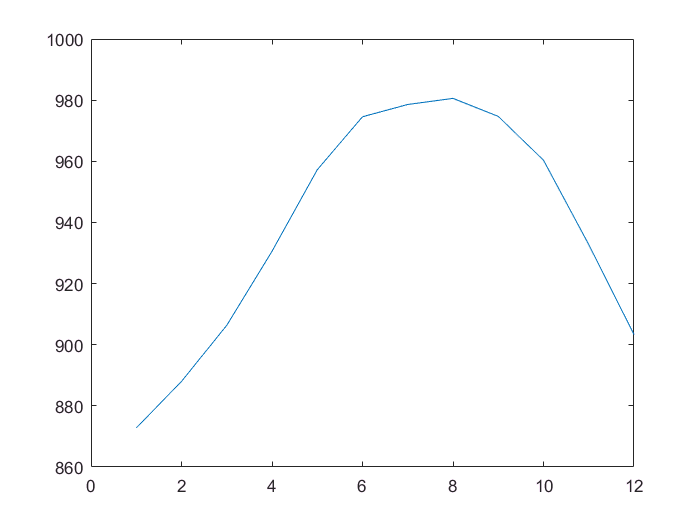

plot(mth,avgWithInflation)

## Mathematical Functions

Convert revenues to billions of dollars, and round to three decimal places (i.e., the nearest million dollars).

revBillion = round(revenue/1e9,3)

revBillion =    1.0e+05 *

    0.6841    0.6952    0.7041    0.7254    0.8034    0.7581    0.8421    0.8351    0.8073    0.8427    0.8392    0.9827    0.9429    0.9946    1.0473    1.0672    1.1496    1.2599    1.3524    1.4954    1.5475    1.5771    1.4360    1.5100    1.7075    1.6638
    0.5572    0.6042    0.6389    0.6502    0.7037    0.6942    0.7502    0.7202    0.6902    0.6868    0.7600    0.8030    0.7907    0.8897    0.9363    0.9341    1.0243    1.2016    1.2045    1.2885    1.3374    1.3284    1.2424    1.3153    1.5338    1.5209
    0.5443    0.5751    0.5905    0.6478    0.6456    0.6468    0.7034    0.6709    0.6885    0.7066    0.6854    0.7721    0.7785    0.8312    0.8525    0.9235    1.0358    1.0854    1.1198    1.2014    1.2414    1.2090    1.1621    1.3016    1.3996    1.4427
    0.5015    0.5256    0.5497    0.5665    0.5766    0.5769    0.6148    0.6095    0.6103    0.6250    0.6219    0.6974    0.7151    0.7357    0.7628    0.8002    0.9220    0.9595    1.0075

Calculate the geometric mean of the prices from 1990 and 2015.

GMprice = sqrt(price(:,1).*price(:,end))

GMprice =    1.0e+03 *

    0.9313
    0.9586
    0.9667
    0.9861
    1.0155
    1.0236
    1.0306
    1.0323
    1.0318
    1.0117


Compare with the arithmetic mean.

AMprice = (price(:,1) + price(:,end))/2

AMprice =    1.0e+03 *

    0.9634
    0.9883
    0.9957
    1.0166
    1.0457
    1.0517
    1.0582
    1.0587
    1.0605
    1.0385


## Statistical Operations

Calculate the average electricity usage for each year.

annual = mean(usage);
plot(yr,annual)

Add the maximum and minimum for each year.

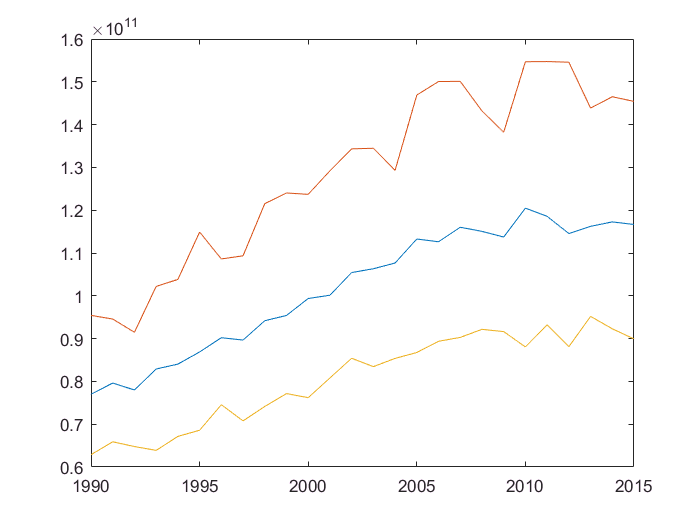

hold on
plot(yr,max(usage))
plot(yr,min(usage))
hold off

Calculate the average electricity usage for each month.

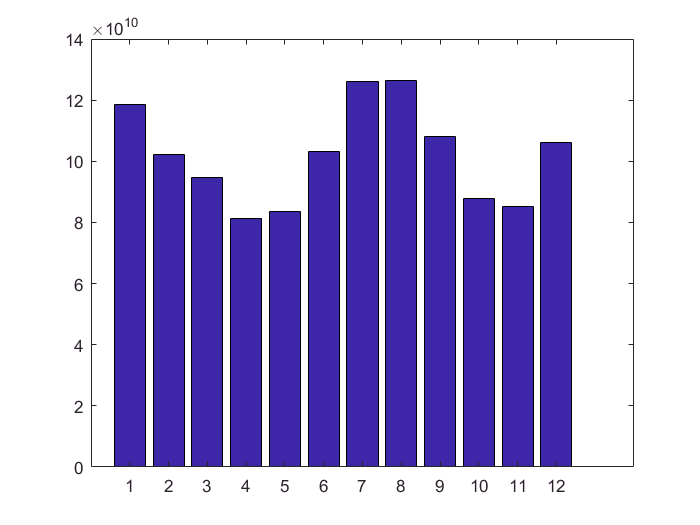

monthly = mean(usage,2);
bar(mth,monthly)

Calculate the median year-over-year change in usage for each month.

YoY = diff(revenue,[],2);
medYoY = median(YoY,2);
bar(mth,medYoY)

doc datafun

## Creating Arrays of Text

Create a cell array of 12 strings. Note the size and type of the result.

M = {'Jan','Feb','Mar','Apr','May','Jun','Jul','Aug','Sep','Oct','Nov','Dec'};

Change the x-axis tick labels to display the months as text.

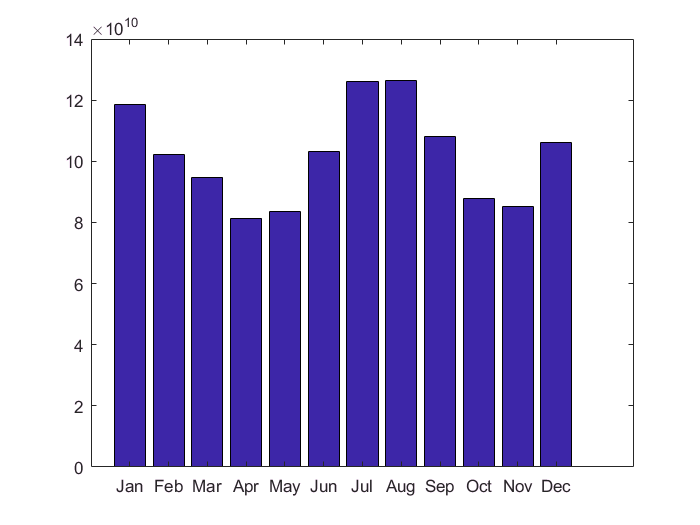

monthly = mean(usage,2);
bar(mth,monthly)
xticks(1:12)
xticklabels(M)

## Plotting Multiple Columns

Plot each year’s electricity usage simultaneously as a function of month.

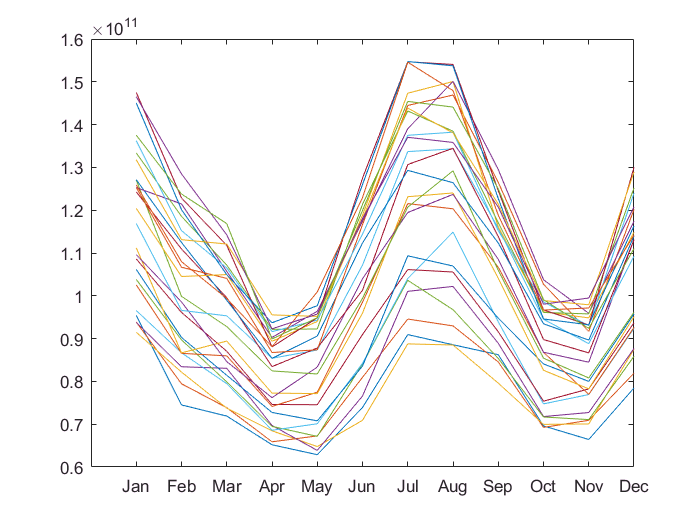

plot(mth,usage)
xticks(1:12)
xticklabels(M)

Plot each month’s electricity usage simultaneously as a function of year.

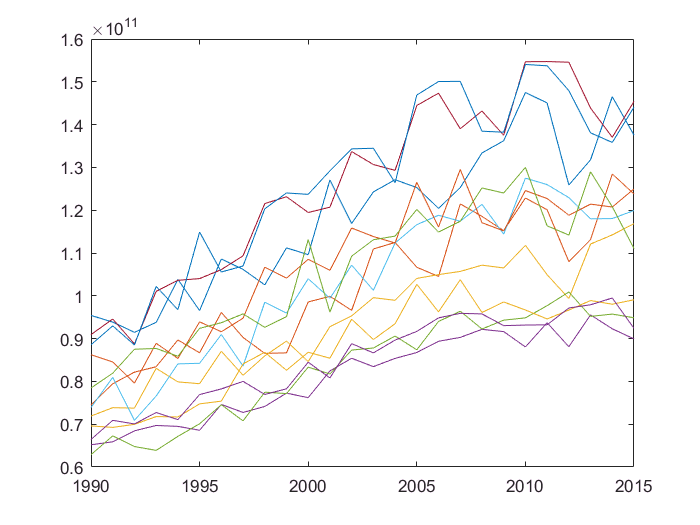

plot(yr,usage')

Plot a time series of revenue for the first month of each quarter.

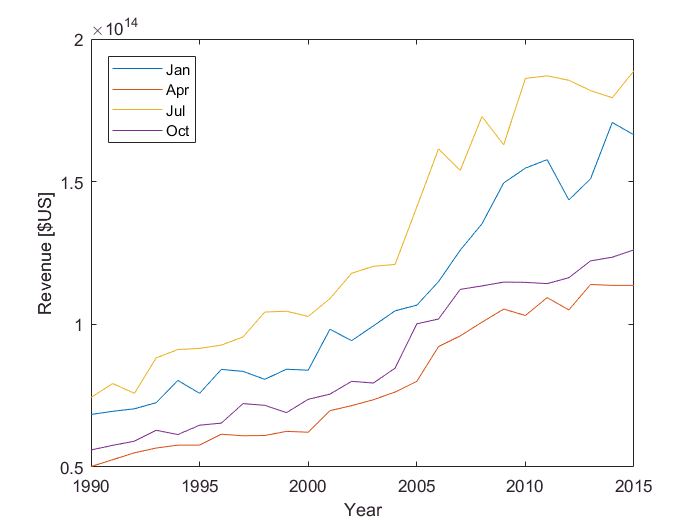

firstmonth = revenue(1:3:12,:)';
plot(yr,firstmonth)
q = {'Jan','Apr','Jul','Oct'};
legend(q,'Location','northwest')
xlabel('Year')
ylabel('Revenue [$US]')

## Matrix Visualization

Visualize the electricity revenue as a surface.

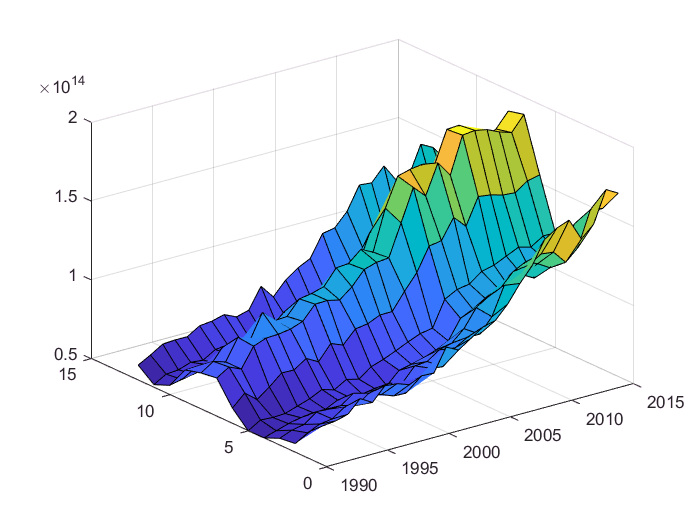

surf(yr,mth,revenue)

## Reshaping

Calculate the average electricity usage over all time.

usageVec = reshape(usage,[],1);
mean(usageVec)

ans = 1.0197e+11

Plot electricity prices as a single time series.

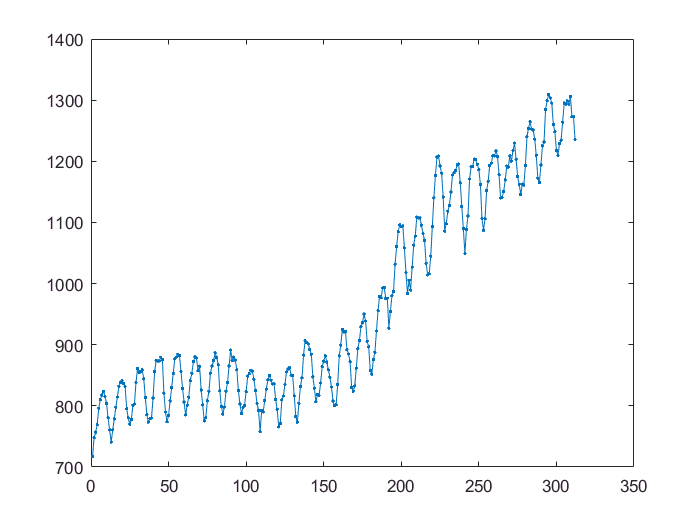

priceVec = reshape(price,[],1);
plot(priceVec,'.-')